# Week 7 Exercise 2

Part (b)

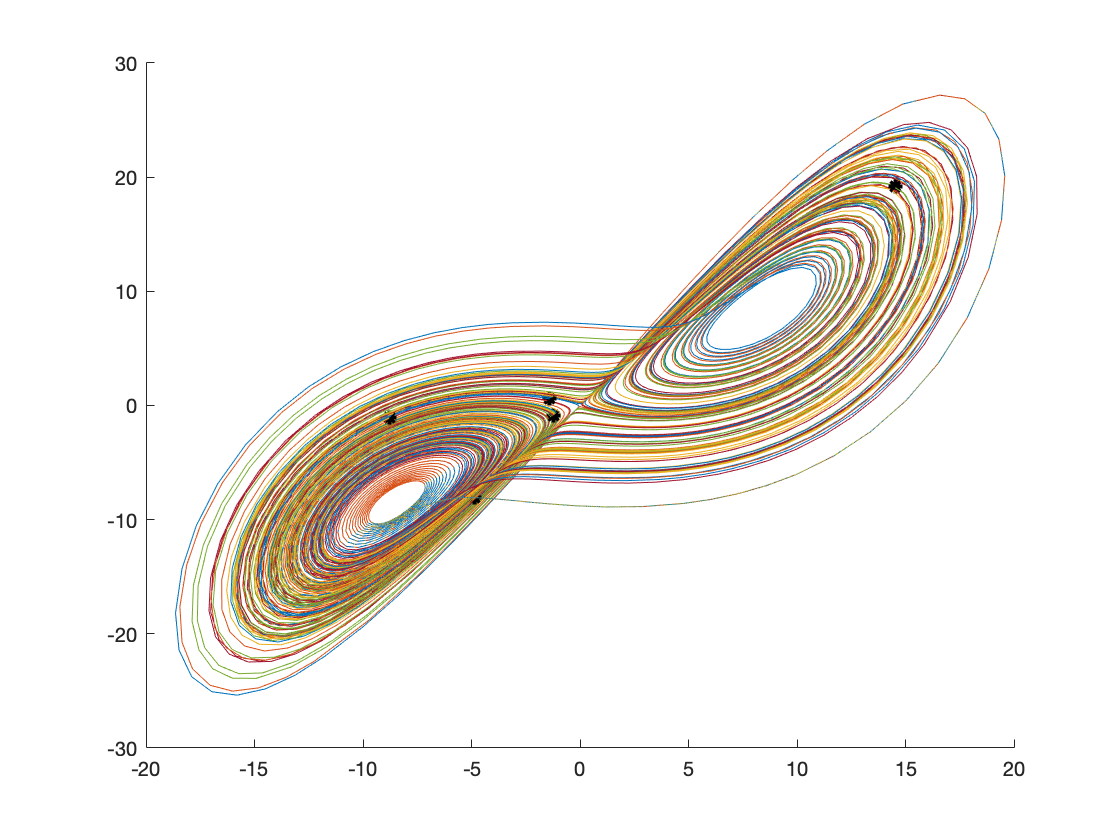

% Constants
a = 10;
b = 28;
c = 8/3;
x0 = [1;1;1];

hold on
for p=1:5  % Execute 5 times
    dx = linspace(-10^-3,10^-3,3)';
    x0 = x0+dx;  % Change initial conditions each iteration
    [t,x] = ode45(@(t,x) Lorentz(x,a,b,c), [0 50], x0);  % Solve the Lorentz functions
    plot3(x(:,1),x(:,2),x(:,3))  % Plot the functions
    plot3(x(end,1),x(end,2),x(end,3), 'k*', 'LineWidth',2)  % Plot the end points
end

Part (a)

function dx = Lorentz(x,a,b,c)
    
    dx(1) = a*(x(2)-x(1));         % x1'
    dx(2) = x(1)*(b-x(3)) - x(2);  % x2'
    dx(3) = x(1)*x(2) - c*x(3);    % x3'
    dx = dx';
end